# XTD_A3: Symmetry Analysis (Event Boundary & Beta Power)

% load('.\XTD_WT_PI_PO_RawLFP.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);



## Compile Data

symRatTR = cell(length(fileDirs), mlb.seqLength);
symRatDEC = cell(length(fileDirs), mlb.seqLength);
symRatMN = cell(length(fileDirs), mlb.seqLength);
persRatTR = cell(length(fileDirs), mlb.seqLength);
persRatDEC = cell(length(fileDirs), mlb.seqLength);
persRatMN = cell(length(fileDirs), mlb.seqLength);
for ani = 1:length(fileDirs)
    for pos = 1:mlb.seqLength
        tempDs = xtd_D{pos,pos,ani};
        temp_symRatTR = nan(size(tempDs,3),length(mlb.obsvTimeVect));
        temp_symRatDEC = nan(size(tempDs,3),length(mlb.obsvTimeVect));
        temp_symRatMN = nan(size(tempDs,3),length(mlb.obsvTimeVect));
        temp_persRatTR = zeros(size(tempDs,3),length(mlb.obsvTimeVect));
        temp_persRatDEC = zeros(size(tempDs,3),length(mlb.obsvTimeVect));
        temp_persRatMN = zeros(size(tempDs,3),length(mlb.obsvTimeVect));
        for trl = 1:size(tempDs,3)
            temp_trialD = tempDs(:,:,trl);
            for t = 10:length(mlb.obsvTimeVect)-10
%                 trVect = temp_trialD(:,t);
%                 decVect = temp_trialD(t,:);
                trVect = smooth(temp_trialD(:,t),'lowess');
                decVect = smooth(temp_trialD(t,:),'lowess');
                mnVect = mean([trVect(:), decVect(:)],2,'omitnan');
                if trVect(t)>0
                    fwdTRlag = find(trVect(t:end)<=0,1,'first');
                    if isempty(fwdTRlag)
                        fwdTRlag = length(trVect)-t;
                    end
                    revTRlag = find(trVect(1:t)<=0,1,'last');
                    if isempty(revTRlag)
                        revTRlag = t;
                    else
                        revTRlag = t-revTRlag;
                    end
                    temp_symRatTR(trl,t) = fwdTRlag - revTRlag;
                    temp_persRatTR(trl,t) = mean([fwdTRlag, revTRlag]);
%                     temp_persRatTR(trl,t) = max([fwdTRlag, revTRlag]);
%                     temp_persRatTR(trl,t) = fwdTRlag;
%                     temp_persRatTR(trl,t) = revTRlag;
                end
                if decVect(t)>0
                    fwdDEClag = find(decVect(t:end)<=0,1,'first');
                    if isempty(fwdDEClag)
                        fwdDEClag = length(decVect)-t;
                    end
                    revDEClag = find(decVect(1:t)<=0,1,'last');
                    if isempty(revDEClag)
                        revDEClag = t;
                    else
                        revDEClag = t-revDEClag;
                    end
                    temp_symRatDEC(trl,t) = fwdDEClag - revDEClag;
                    temp_persRatDEC(trl,t) = mean([fwdDEClag, revDEClag]);
%                     temp_persRatDEC(trl,t) = max([fwdDEClag, revDEClag]);
%                     temp_persRatDEC(trl,t) = fwdDEClag;
%                     temp_persRatDEC(trl,t) = revDEClag;
                end
                if mnVect(t)>0
                    fwdMNlag = find(mnVect(t:end)<=0,1,'first');
                    if isempty(fwdMNlag)
                        fwdMNlag = length(decVect)-t;
                    end
                    revMNlag = find(mnVect(1:t)<=0,1,'last');
                    if isempty(revMNlag)
                        revMNlag = t;
                    else
                        revMNlag = t-revMNlag;
                    end
                    temp_symRatMN(trl,t) = fwdMNlag - revMNlag;
                    temp_persRatMN(trl,t) = mean([fwdMNlag,revMNlag]);
%                     temp_persRatMN(trl,t) = max([fwdMNlag,revMNlag]);
%                     temp_persRatMN(trl,t) = fwdMNlag;
%                     temp_persRatMN(trl,t) = revMNlag;
                end
            end
        end
        symRatTR{ani,pos} = temp_symRatTR;
        symRatDEC{ani,pos} = temp_symRatDEC;
        symRatMN{ani,pos} = temp_symRatMN;
%         symRatTR{ani,pos} = smooth(temp_symRatTR, 'lowess');
%         symRatDEC{ani,pos} = smooth(temp_symRatDEC, 'lowess');
%         symRatMN{ani,pos} = smooth(temp_symRatMN, 'lowess');
        persRatTR{ani,pos} = temp_persRatTR;
        persRatDEC{ani,pos} = temp_persRatDEC;
        persRatMN{ani,pos} = temp_persRatMN;
    end
end

trialLIGHTlat = lat_PrtLight(2:end,:)';
% trialLIGHTlat = cell2mat(trialLIGHTlat(:)');
trialPIlat = lat_TrlStart(:);
% trialPIlat = cell2mat(trialPIlat(:)');
trialSIGlat = lat_RwdSig(:);
% trialSIGlat = cell2mat(trialSIGlat(:)');
trialPOlat = lat_TrlEnd(:);
% trialPOlat = cell2mat(trialPOlat(:)');
trialRWDlat = lat_Rwd(:);
% trialRWDlat = cell2mat(trialRWDlat(:)');
nxtTrlLats = lat_NextTrl(:);
% nxtTrlLats = cell2mat(nxtTrlLats(:)');
prevTrlLats = lat_PrevTrl(:);
% prevTrlLats = cell2mat(prevTrlLats(:)');

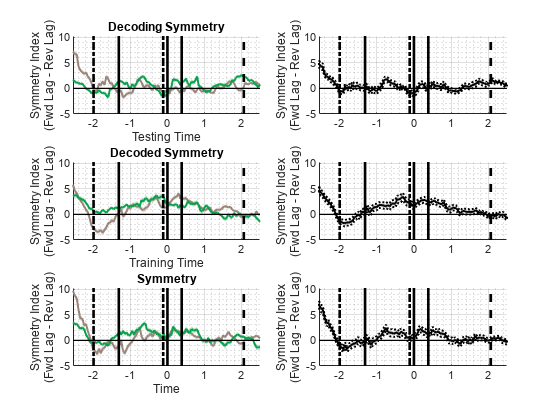


figure;
sps = nan(3,2);
% for p = 1:mlb.seqLength
for p = 2:mlb.seqLength-1
    sps(1) = subplot(3,2,1);
    tempTR = cell2mat(symRatTR(:,p));
    %     tempTR = (tempTR - mean(tempTR(:),'omitnan')) ./ std(tempTR(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempTR,1,0,mlb.PositionColors(p,:));
    sps(2) = subplot(3,2,3);
    tempDEC = cell2mat(symRatDEC(:,p));
    %     tempDEC = (tempDEC - mean(tempDEC(:),'omitnan')) ./ std(tempDEC(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempDEC,1,0,mlb.PositionColors(p,:));
    sps(3) = subplot(3,2,5);
    tempMN = cell2mat(symRatMN(:,p));
    %     tempMN = (tempMN - mean(tempMN(:),'omitnan')) ./ std(tempMN(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempMN,1,0,mlb.PositionColors(p,:));
end
sps(4) = subplot(3,2,2);
% tempTR = cell2mat(symRatTR);
tempTR = cell2mat(reshape(symRatTR(:,2:mlb.seqLength-1),[numel(symRatTR(:,2:mlb.seqLength-1)),1]));
% tempTR = (tempTR - mean(tempTR(:),'omitnan')) ./ std(tempTR(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempTR,1,0.05,'k');
sps(5) = subplot(3,2,4);
% tempDEC = cell2mat(symRatDEC);
tempDEC = cell2mat(reshape(symRatDEC(:,2:mlb.seqLength-1), [numel(symRatDEC(:,2:mlb.seqLength-1)),1]));
% tempDEC = (tempDEC - mean(tempDEC(:),'omitnan')) ./ std(tempDEC(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempDEC,1,0.05,'k');
sps(6) = subplot(3,2,6);
% tempMN = cell2mat(symRatMN);
tempMN = cell2mat(reshape(symRatMN(:,2:mlb.seqLength-1), [numel(symRatMN(:,2:mlb.seqLength-1)),1]));
% tempMN = (tempMN - mean(tempMN(:),'omitnan')) ./ std(tempMN(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempMN,1,0.05,'k');
linkaxes(sps,'xy');

for plt = 1:6
    subplot(3,2,plt);
    if plt==1
        title('Decoding Symmetry');
        xlabel('Testing Time');
    elseif plt==3
        title('Decoded Symmetry');
        xlabel('Training Time');
    elseif plt==5
        title('Symmetry');
        xlabel('Time');
    end
    ylabel([{'Symmetry Index'};{'(Fwd Lag - Rev Lag)'}]);
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);

    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(get(gca, 'xlim'), zeros(1,2), '-k', 'linewidth', 1);
    grid on;
    grid minor;
end

## LFP Stuff Again because I hate myself

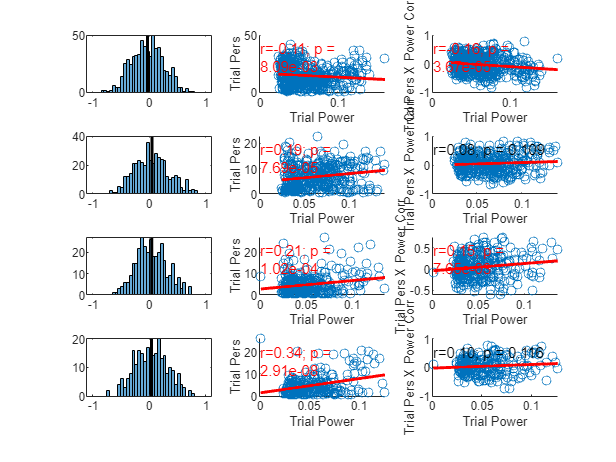

trialCorr_Power = cell(mlb.seqLength, length(fileDirs));
trialMean_Power = cell(mlb.seqLength, length(fileDirs));
trialMean_Pers = cell(mlb.seqLength, length(fileDirs));
% figure;
for ani = 1:length(fileDirs)
    for pos = 1:mlb.seqLength
        curPos_Power = xtd_LFPpower{pos,ani};
%         curPos_Pers = persRatTR{ani,pos};
        curPos_Pers = persRatDEC{ani,pos};
%         curPos_Pers = persRatMN{ani,pos};
        curPos_TrialDur = mask_Trial{pos,ani};
        if size(curPos_Power,2) ~= size(curPos_Pers,1)
            error('E1: Dimension Mismatch');
        end
        temp_trialCorr_Power = nan(1,size(curPos_Power,2));
        temp_trialMean_Power = nan(1,size(curPos_Power,2));
        temp_trialMean_Pers = nan(1,size(curPos_Power,2));
        for trl = 1:size(curPos_Power,2)
            temp_TrialMask = curPos_TrialDur(:,trl);
            temp_Power = curPos_Power(temp_TrialMask,trl);
            temp_curTrl_Pers = smooth(curPos_Pers(trl,:),'lowess');
%             temp_curTrl_Pers = interp1(mlb.obsvTimeVect(~isnan(curPos_Pers(trl,:))), curPos_Pers(trl,~isnan(curPos_Pers(trl,:))),'spline')';
            curTrl_Pers = temp_curTrl_Pers(temp_TrialMask);
            temp_trialCorr_Power(trl) = corr(temp_Power, curTrl_Pers);
            temp_trialMean_Power(trl) = mean(temp_Power);
            temp_trialMean_Pers(trl) = mean(curTrl_Pers);
        end
        trialCorr_Power{pos,ani} = temp_trialCorr_Power;
        trialMean_Power{pos,ani} = temp_trialMean_Power;
        trialMean_Pers{pos,ani} = temp_trialMean_Pers;
%         subplot(mlb.seqLength, length(fileDirs), sub2ind([length(fileDirs), mlb.seqLength],ani,pos));
%         histogram(trialCorr_Power{pos,ani}, -1:0.05:1);
%         title(sprintf('A%i_P%i', ani, pos));
    end
end
figure;
for pos = 1:mlb.seqLength
    subplot(4,3,sub2ind([3,4],1,pos));
    histogram(cell2mat(trialCorr_Power(pos,:)),-1:0.05:1);
    hold on;
    plot(repmat(mean(cell2mat(trialCorr_Power(pos,:)),'omitnan'), [1,2]), get(gca, 'ylim'), '-k', 'linewidth', 2);
    subplot(4,3,sub2ind([3,4],2,pos));
    mlb.CorrScatPlot(cell2mat(trialMean_Power(pos,:))', cell2mat(trialMean_Pers(pos,:))', 'Trial Power', 'Trial Pers',[]);
    subplot(4,3,sub2ind([3,4],3,pos));
    mlb.CorrScatPlot(cell2mat(trialMean_Power(pos,:))', cell2mat(trialCorr_Power(pos,:))', 'Trial Power', 'Trial Pers X Power Corr',[]);
end

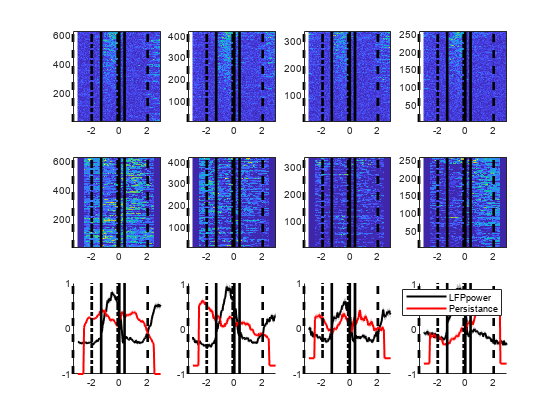


figure;
sps = nan(mlb.seqLength, 3);
for pos = 1:mlb.seqLength
%     curPos_Pers = cell2mat(persRatTR(:,pos));
    curPos_Pers = cell2mat(persRatDEC(:,pos));
%     curPos_Pers = cell2mat(persRatMN(:,pos));
%     curPos_Pers = cell2mat(symRatTR(:,pos));
    curPos_Power = cell2mat(xtd_LFPpower(pos,:))';
% 
    curPos_MeanPower = cell2mat(trialMean_Power(pos,:))';
    mnPowerSorted_Power = sortrows([curPos_MeanPower, curPos_Power],1);
    mnPowerSorted_Pers = sortrows([curPos_MeanPower, curPos_Pers],1);
% 
%     curPos_MeanPers = cell2mat(trialMean_Pers(pos,:))';
%     mnPowerSorted_Power = sortrows([curPos_MeanPers, curPos_Power],1);
%     mnPowerSorted_Pers = sortrows([curPos_MeanPers, curPos_Pers],1);

%     curPos_TrialDur = sum(cell2mat(mask_Trial(pos,:)))';
%     mnPowerSorted_Power = sortrows([curPos_TrialDur, curPos_Power],1);
%     mnPowerSorted_Pers = sortrows([curPos_TrialDur, curPos_Pers],1);

    mnPowerSorted_Power = mnPowerSorted_Power(:,2:end);
    mnPowerSorted_Pers = mnPowerSorted_Pers(:,2:end);

    sps(sub2ind([mlb.seqLength, 3], pos, 1)) = subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3], pos, 1));
    imagesc(mlb.obsvTimeVect, 1:size(mnPowerSorted_Power,1),mnPowerSorted_Power);
    hold on;
    set(gca, 'ydir', 'normal');
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    
    sps(sub2ind([mlb.seqLength, 3], pos, 2)) = subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3], pos, 2));
    imagesc(mlb.obsvTimeVect, 1:size(mnPowerSorted_Pers,1), mnPowerSorted_Pers);
    hold on;
    set(gca, 'ydir', 'normal');
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);

    sps(sub2ind([mlb.seqLength, 3], pos, 3)) = subplot(3,mlb.seqLength, sub2ind([mlb.seqLength, 3], pos, 3));
    p(1) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, zscore(mnPowerSorted_Power,0,'all'),1,0, 'k');
    p(2) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, zscore(mnPowerSorted_Pers,0,'all'),1,0, 'r');    
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
end
linkaxes(sps, 'x');
legend(p, [{'LFPpower'}, {'Persistance'}]);

## Plot Persistence for High vs Low Beta Power Trials

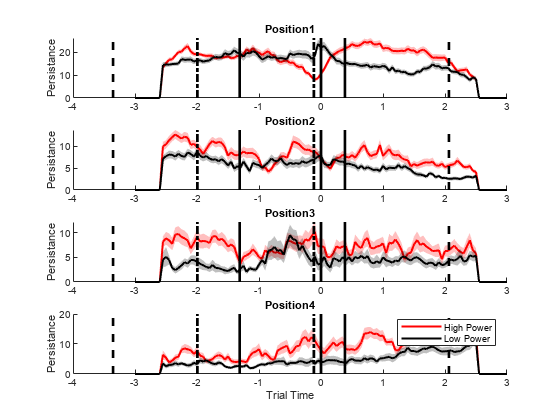

figure; 
sps = nan(1,4);
for pos = 1:mlb.seqLength
%     curPos_Pers = cell2mat(persRatTR(:,pos));
    curPos_Pers = cell2mat(persRatDEC(:,pos));
%     curPos_Pers = cell2mat(persRatMN(:,pos));
%     curPos_Pers = cell2mat(symRatTR(:,pos));
    curPos_Power = cell2mat(xtd_LFPpower(pos,:))';    
    curPos_MeanPower = cell2mat(trialMean_Power(pos,:))';
    curPos_HighPowerLog = curPos_MeanPower > (mean(curPos_MeanPower) + std(curPos_MeanPower));
    curPos_LowPowerLog = curPos_MeanPower < (mean(curPos_MeanPower) - std(curPos_MeanPower));
    
    sps(pos) = subplot(mlb.seqLength,1,pos);
    p(1) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_Pers(curPos_HighPowerLog,:),1,0, 'r');
    p(2) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_Pers(curPos_LowPowerLog,:),1,0, 'k');
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    title(sprintf('Position%i',pos));
    ylabel('Persistance');
end
linkaxes(sps, 'x');
legend(p, [{'High Power'}, {'Low Power'}]);
xlabel('Trial Time');

## Plot Symmetry Relative to Peak Beta Power

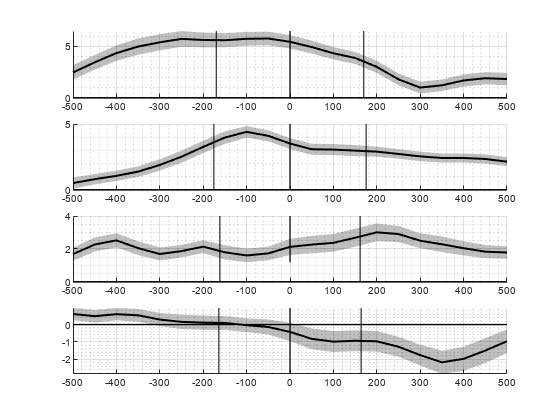

numNdxs = 10;
peakAligned_Sym = cell(mlb.seqLength,1);
peakAligned_PeakPower = cell(1,mlb.seqLength);
peakAligned_PeakLocs = cell(1,mlb.seqLength);
peakAligned_PeakWidths = cell(1,mlb.seqLength);
peakAligned_PeakProms = cell(1,mlb.seqLength);
for pos = 1:mlb.seqLength
%     curPos_Sym = cell2mat(symRatTR(:,pos));
    curPos_Sym = cell2mat(symRatDEC(:,pos));
%     curPos_Sym = cell2mat(symRatMN(:,pos));
    curPos_Power = cell2mat(xtd_LFPpower(pos,:))';    
    curPos_TrialMask = cell2mat(mask_Trial(pos,:))';
    curTrl_Sym = cell(size(curPos_Power,1),1);
    curTrl_PeakPower = cell(size(curPos_Power,1),1);
    curTrl_PeakLocs = cell(size(curPos_Power,1),1);
    curTrl_PeakWidths = cell(size(curPos_Power,1),1);
    curTrl_PeakProms = cell(size(curPos_Power,1),1);
    for trl = 1:size(curPos_Sym,1)
        temp_Sym = smooth(curPos_Sym(trl,:), 'lowess');
%         temp_Sym = interp1(mlb.obsvTimeVect(~isnan(curPos_Sym(t,:))), curPos_Sym(t,~isnan(curPos_Sym(t,:))), mlb.obsvTimeVect, 'spline');
        temp_Power = smooth(curPos_Power(trl,:));
        temp_TrialMask = curPos_TrialMask(trl,:);
        [tempPeak_Power,...
            tempPeak_Loc,...
            tempPeak_Width,...
            tempPeak_Prom] = findpeaks(temp_Power,mlb.obsvTimeVect);
        trlBounds = [min(mlb.obsvTimeVect(temp_TrialMask)) max(mlb.obsvTimeVect(temp_TrialMask))];
        trialLocLog = tempPeak_Loc>trlBounds(1) & tempPeak_Loc<trlBounds(2);
        curTrl_PeakPower{trl} = tempPeak_Power(trialLocLog)';
        curTrl_PeakLocs{trl} = tempPeak_Loc(trialLocLog)';
        curTrl_PeakWidths{trl} = tempPeak_Width(trialLocLog)';
        curTrl_PeakProms{trl} = tempPeak_Prom(trialLocLog)';
        temp_PeakSymVals = nan(sum(trialLocLog),numNdxs*2+1);
        for pk = 1:sum(trialLocLog)
            curPkLoc = find(mlb.obsvTimeVect==curTrl_PeakLocs{trl}(pk));
            if isempty(curPkLoc)
                error('No Findy Peak.... You stupid?');
            end
            temp_PeakSymVals(pk,:) = temp_Sym(curPkLoc-numNdxs:curPkLoc+numNdxs);
        end
        curTrl_Sym{trl} = temp_PeakSymVals;
    end
    peakAligned_Sym{pos} = curTrl_Sym;
    peakAligned_PeakPower{pos} = curTrl_PeakPower;
    peakAligned_PeakLocs{pos} = curTrl_PeakLocs;
    peakAligned_PeakWidths{pos} = curTrl_PeakWidths;
    peakAligned_PeakProms{pos} = curTrl_PeakProms;
end
all_PeakPower = cellfun(@(a){[a{:}]},peakAligned_PeakPower);
all_PeakPower = [all_PeakPower{:}];
all_PeakProms = cellfun(@(a){[a{:}]},peakAligned_PeakProms);
all_PeakProms = [all_PeakProms{:}];
all_PeakWidth = cellfun(@(a){[a{:}]}, peakAligned_PeakWidths);
all_PeakWidth = [all_PeakWidth{:}];
figure;
for pos = 1:mlb.seqLength
    pos_Sym = cell2mat(peakAligned_Sym{pos});
    pos_PeakPower = cell2mat(peakAligned_PeakPower{pos}')';
    pos_PeakWidth = cell2mat(peakAligned_PeakWidths{pos}')';
    pos_PeakProms = cell2mat(peakAligned_PeakProms{pos}')';
%     symLog = pos_PeakPower>(mean(all_PeakPower));
%     symLog = pos_PeakWidth>(mean(all_PeakWidth));
%     symLog = (pos_PeakPower>(mean(all_PeakPower))) &  (pos_PeakWidth>(mean(all_PeakWidth)));
    symLog = (pos_PeakPower>(mean(all_PeakPower))) &  (pos_PeakWidth>(mean(all_PeakWidth))) & (pos_PeakProms>(mean(all_PeakProms)));
%     symLog = true(size(pos_PeakPower));
    subplot(4,1,pos);
    mlb.PlotMeanVarLine(mlb.dsRate*numNdxs*-1:mlb.dsRate:mlb.dsRate*numNdxs, pos_Sym(symLog,:) ,1,0,'k');
    plot(zeros(1,2), get(gca, 'ylim'), '-k', 'linewidth', 1);
    plot(get(gca, 'xlim'), zeros(1,2), '-k', 'linewidth', 1);
    plot(repmat(mean(pos_PeakWidth)*-1000,[1,2]), get(gca, 'ylim'), '-k');
    plot(repmat(mean(pos_PeakWidth)*1000,[1,2]), get(gca, 'ylim'), '-k');
    grid on;
    grid minor;
end